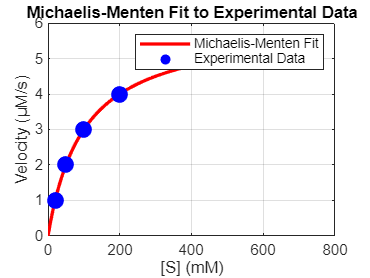

clc; clear; close all;

%% Given Experimental Data
S0 = [20, 50, 100, 200, 500]; % Substrate concentration (mM)
V0 = [1.0, 2.0, 3.0, 4.0, 5.0]; % Velocity (μM/s)
Vmax = 6.0; % Maximum velocity (μM/s)

%% Fit the Data to Michaelis-Menten Equation
michaelis_menten = @(Km, S) (Vmax .* S) ./ (Km + S);

% Use non-linear regression to fit Km
Km_fit = fminsearch(@(Km) sum((michaelis_menten(Km, S0) - V0).^2), 50); % Initial guess

%% Generate Michaelis-Menten Curve
S_fit = linspace(0, max(S0)*1.5, 100);
V_fit = michaelis_menten(Km_fit, S_fit);

%% Plot Michaelis-Menten Curve
figure;
plot(S_fit, V_fit, 'r-', 'LineWidth', 2); hold on;
scatter(S0, V0, 100, 'b', 'filled');
xlabel('[S] (mM)');
ylabel('Velocity (μM/s)');
title('Michaelis-Menten Fit to Experimental Data');
legend('Michaelis-Menten Fit', 'Experimental Data');
grid on;

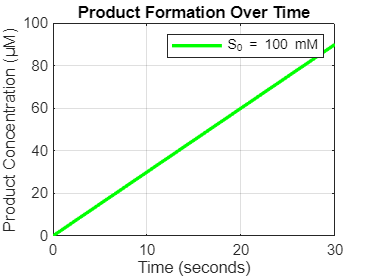


%% Simulate Product Formation Over Time
% Define ODE function for product formation
product_formation = @(t, P) (Vmax * S0(3)) / (Km_fit + S0(3)); % S0(3) = 100 mM example

% Solve ODE using ode45
tspan = [0 30]; % Simulate for 30 seconds
P0 = 0; % Initial product concentration
[t_sol, P_sol] = ode45(@(t, P) product_formation(t, P), tspan, P0);

%% Plot Product Formation Over Time
figure;
plot(t_sol, P_sol, 'g-', 'LineWidth', 2);
xlabel('Time (seconds)');
ylabel('Product Concentration (μM)');
title('Product Formation Over Time');
legend(['S_0 = ' num2str(S0(3)) ' mM']);
grid on;


%% Display Results
disp(['Estimated Km: ', num2str(Km_fit), ' mM']);

Estimated Km: 100 mM
